clc
close all
clear
warning off
fc =0.5;
T=1;
rok = 0.25; % Power Splitting factor
tou = 0.45; % Time Switching Factor
dsd=0.2:0.1:2;% Distance between Sourse and 
ds=length(dsd);
r=0.1;
theta=pi/3;
dsd=dsd';
dsr=zeros(1,ds)+r;
dsr = dsr';
drd=sqrt(dsd.^2+dsr.^2 - (2*dsd.*dsr.*cos(theta)));
b3=10^(1.976); 
bet=10^(-0.59);
B3=b3.*dsd.^(-bet);
cost=100;
B33=B3/cost;
BB3= b3.*dsr.^(-bet);
BB33=BB3/cost;
fl=ones(ds,1).*fc;
ITER=400;
% Frequecy ranges without Additinal Bandwidth
for i =1:cost
    fd11(:,i)= fc+((i-1).*B33);
    
end

for i =1:cost
    fd21(:,i)= fc+((i-1).*BB33);
    
end
% Additional Bandwidth CAlculation 

FADD21(:,1) = fd11(:,100) ;
FADD21(:,2) = fd21(:,100);
FADD31 = (FADD21(:,2) - FADD21(:,1))/99;

for i=1:length(dsd)
FADD41(i,:) = FADD21(i,1):FADD31(i,1):FADD21(i,2); %% Frequecy ranges with Additional bandwidth
end

% Ambient losses Calculation for Normal bandwidth
s=0;
w=6.67;
for i=1:length(dsd)
    g(i,:)=fd11(i,:);
  for j=1:cost     
    if (g(i,j)<=0.01)
       NLindbsd(i,j)=17-(30*log10(g(i,j)));
    else
    if (g(i,j)>0.01 && g(i,j)<=0.1 )
     NLindbsd(i,j)=40+(20*(s-0.5))+(26*log10(g(i,j)))-(60*log10((g(i,j)+0.03)));
    else
     if (g(i,j)>0.1 && g(i,j)<=100)
        NLindbsd(i,j)=50+(7.5*w.^(0.5))+(20*log10(g(i,j)))-(40*log10((g(i,j)+0.4)));
     else
         if(g(i,j)>100)
             NLindbsd(i,j)=-15+(20*log10(g(i,j)));
         end
     end
    end
   end
   end
end
% Ambient losses Calculation for Additional Bandwidth
for i=1:length(dsr)
    h(i,:)=FADD41(i,:);
  for j=1:cost     
    if (h(i,j)<=0.01)
       NLindbsd2(i,j)=17-(30*log10(h(i,j)));
    else
    if (h(i,j)>0.01 && h(i,j)<=0.1 )
     NLindbsd2(i,j)=40+(20*(s-0.5))+(26*log10(h(i,j)))-(60*log10((h(i,j)+0.03)));
    else
     if (h(i,j)>0.1 && h(i,j)<=100)
        NLindbsd2(i,j)=50+(7.5*w.^(0.5))+(20*log10(h(i,j)))-(40*log10((h(i,j)+0.4)));
     else
         if(h(i,j)>100)
             NLindbsd2(i,j)=-15+(20*log10(h(i,j)));
         end
     end
    end
   end
   end
end

% Transmission losses Calculation

H=100;
Ph=8.1;
S=34.5;
T=4;
c= 1448.96 + (4.591*T) - (0.05304*T*T) + (0.0002374*T^3) + (1.340*(S-35))+ (0.0163*H)+(1.675*10^-7*H^2) - (0.01025*T*(S-35)) -(7.139*10^-14*T*H^3);
f33= 2.8.*(S/35)^0.5.*10.^(4-(1245./(273+T)));
f22= (8.17.*10.^(8-(1990./(273+T))))./(1+(0.0018.*(S-35)));
A1=(8.68./c).*(10.^((0.78.*Ph)-5));
P1=1;
A2=21.44.*(S/c).*(1+(0.025.*T));
P2=1-(1.37.*10^-4.*H)+(6.2.*10^-9.*H^2);
if (T>20)
    A3=(4.937*10^-4)-(2.59*10^-5.*T)+(9.11*10^-7.*T^2)-(1.50*10^-8.*T^3);
else
    A3=(3.964*10^-4)-(1.146*10^-5.*T)+(1.45*10^-7.*T^2)-(6.5*10^-10.*T^3);
end

P3=1-(3.83.*10^-5.*H)+(4.9.*10^-10.*H^2);

ad11=((A1.*P1.*f33.*g.^2)./(g.^2+f33^2))+((A2.*P2.*f22.*g.^2)./(g.^2+f22^2))+(A3.*P3.*g.^2);
ad21=((A1.*P1.*f33.*h.^2)./(h.^2+f33^2))+((A2.*P2.*f22.*h.^2)./(h.^2+f22^2))+(A3.*P3.*h.^2);

afindbsd1=(10.*log10(1000.*dsd)) + (ad11.*dsd);
afindbsd2=(10.*log10(1000.*dsr)) + (ad11.*dsr);
afindbd1d2=(10.*log10(1000.*drd)) + (ad11.*drd);

ADDafindbsd2=(10.*log10(1000.*dsr)) + (ad21.*dsr); 

AAN = 10;
AFNLsd1indbshallow=afindbsd1+NLindbsd+AAN;
AFNLsd2indbshallow=afindbsd2+NLindbsd+AAN;
AFNLd1d2indbshallow=afindbd1d2+NLindbsd+AAN;

ADDAFNLsd2indbshallow = ADDafindbsd2+NLindbsd2+AAN;
% Energy harvesting 
% Define the values of Pelec and η
Ptx=10; %  in watts
Pelec=Ptx;
eta = 0.7; % Efficiency
DI = 0;
RVS=-125; 
% Calculate SL using the equation
SL = 170.8 + 10 * log10(Pelec) + 10 * log10(eta)+DI;
% Calculate AL using the equation
a=((A1.*P1.*f33.*g.^2)./(g.^2+f33^2))+((A2.*P2.*f22.*g.^2)./(g.^2+f22^2))+(A3.*P3.*g.^2);
AL=(10.*log10(dsr.*1000)) + ((a).*dsr)+AAN;
RL = SL-AL; %Rceived Level
RLADD = SL - ADDafindbsd2;
Ph= 0.007*10.^((RLADD+RVS)/10);
Ph2= 0.007*10.^(rok*(RL+RVS)/10);% Power Harvested in powerspliting
Ph3= ((2*tou)/(1-tou))*0.007*10.^((RL+RVS)/10);% Power harvested in time switching
Phps= Ph+Ph2;% Powerspliiting with additonal Bandwidth
Phts= Ph+Ph3;% Timeswitching with additional BandwidthSNR Calculation
tempsd=SL-AFNLsd2indbshallow; % SNR between source and destination
tempsr=SL-AFNLsd1indbshallow; % SNR between source and Relay
temprd=SL-AFNLd1d2indbshallow;% SNR between Relay and destination

% SNR calculation

snrsd=10.^(tempsd/10); % SNRSD 
snrsr=10.^(tempsr/10); % SNRSR 
snrrd=10.^(temprd/10); % SNRRD 


SLPH = 170.8 + 10 * log10(Ph2) + 10 * log10(eta)+DI;
tempsrph2=SLPH-AFNLsd1indbshallow;%% CASE-1
SLPHPS = 170.8 + 10 * log10(Phps) + 10 * log10(eta)+DI;
tempsrPhps=SLPHPS-AFNLsd1indbshallow;%% CASE-2
SLPH3 = 170.8 + 10 * log10(Ph3) + 10 * log10(eta)+DI;
tempsrPh3=SLPH3-AFNLsd1indbshallow;%% CASE-3
SLPHTS = 170.8 + 10 * log10(Phts) + 10 * log10(eta)+DI;
tempsrPhTS=SLPHTS-AFNLsd1indbshallow;%% CASE-3

snrsrPH=10.^(tempsrph2/10);
snrsrPHPS=10.^(tempsrPhps/10);
snrsrPH3=10.^(tempsrPh3/10);
snrsrPhTS=10.^(tempsrPhTS/10);
epsmain=0.1;
a2=0.05;
a1=1-a2;
N=100;
ii=length(dsd);
hsd=(1/sqrt(2))*(randn(N,1)+1i*randn(N,1));
hsr=(1/sqrt(2))*(randn(N,1)+1i*randn(N,1));
hrd=(1/sqrt(2))*(randn(N,1)+1i*randn(N,1));
HSD=abs(hsd).^2;

HSR=1*abs(hsr).^2;
HRD=1*abs(hrd).^2;

%% Ergodic rate for PS without additional bandwidth - CASE 1
for p=1:length(epsmain)
    p
eps1=epsmain(p);
for j=1:N    
eps=eps1;
GCNOMA11(:,:,j) = 0.5 * log2(1 + ((a2 * (1 - rok) * snrsr * HSR(j)) ./ ((eps1*a1 * (1 - rok) * snrsr * HSR(j)) + 1)));

GCNOMA22(:,:,j) = 0.5 * ( ...
    log2(1 + max(((a1 * snrsd * HSD(j)) ./ ((a2 * snrsd * HSD(j)) + 1)), ...
                 (snrsrPH * HRD(j)))) );
    
for i=1:ii
GCNOMA11main(i,:,j)=trapz(g(i,:),GCNOMA11(i,:,j));
GCNOMA22main(i,:,j)=trapz(g(i,:),GCNOMA22(i,:,j));

end
GCNOMAmain(j,:)=GCNOMA11main(:,:,j)+GCNOMA22main(:,:,j);


end
GmainCNOMA111(p,:)=mean(GCNOMAmain);

end

p = 1


%% Ergodic rate for PS with additional bandwidth - CASE 2

for p=1:length(epsmain)
    p
eps1=epsmain(p);
for j=1:N    
eps=eps1;
GCNOMA33(:,:,j) =0.5 * log2(1 + ((a2 * (1 - rok) * snrsr * HSR(j)) ./ ((eps1*a1 * (1 - rok) * snrsr * HSR(j)) + 1)));


GCNOMA44(:,:,j) = 0.5 * log2(1 + max(((a1 * snrsd * HSD(j)) ./ ((a2 * snrsd * HSD(j)) + 1)), ...
                                     (snrsrPHPS * HRD(j))));


for i=1:ii
GCNOMA33main(i,:,j)=trapz(g(i,:),GCNOMA33(i,:,j));
GCNOMA44main(i,:,j)=trapz(g(i,:),GCNOMA44(i,:,j));

end
GCNOMAmain(j,:)=GCNOMA33main(:,:,j)+GCNOMA44main(:,:,j);


end
GmainCNOMA222(p,:)=mean(GCNOMAmain);

end

p = 1

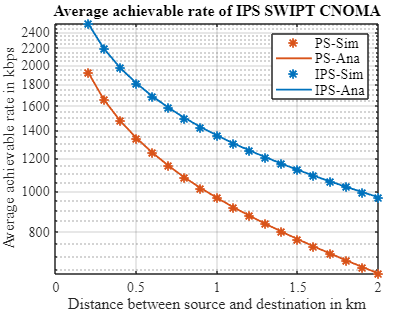

%% Plots for power splitting
figure
semilogy(dsd,GmainCNOMA111,'r*','MarkerSize',8,'color', [0.8500 0.3250 0.0980],'LineWidth',1.5)
hold on;
grid on;
semilogy(dsd,GmainCNOMA111,'r-','MarkerSize',8,'color', [0.8500 0.3250 0.0980],'LineWidth',1.5)
hold on;
semilogy(dsd,GmainCNOMA222,'b*','MarkerSize',8,'color',[0 0.4470 0.7410],'LineWidth',1.5)
hold on;
semilogy(dsd,GmainCNOMA222,'b-','MarkerSize',8,'color',[0 0.4470 0.7410],'LineWidth',1.5)
hold on;
xlabel('Distance between source and destination in km', 'FontName', 'Times New Roman', 'FontSize', 14);
ylabel('Average achievable rate in kbps', 'FontName', 'Times New Roman', 'FontSize', 16);
lgd = legend('PS-Sim', 'PS-Ana', 'IPS-Sim', 'IPS-Ana');
set(lgd, 'Location', 'northeast', 'FontSize', 12, 'FontName', 'Times New Roman'); % Legend font and location
title('Average achievable rate of IPS SWIPT CNOMA', 'FontName', 'Times New Roman', 'FontSize', 14);
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12); % Axis tick labels font



%% Ergodic rate for TS without additional bandwidth - CASE 3

for p=1:length(epsmain)
    p
eps1=epsmain(p);
for j=1:N    
eps=eps1;
GCNOMAT33(:,:,j) =  ((1-tou)/2)*log2(1 + ((a2 * (1 - rok) * snrsr * HSR(j)) ./ ((eps1*a1 * (1 - rok) * snrsr * HSR(j)) + 1)));

GCNOMAT44(:,:,j) = ((1 - tou) / 2) * ( ...
    log2(1 + max(((a1 * snrsd * HSD(j)) ./ ((a2 * snrsd * HSD(j)) + 1)), ...
                 (snrsrPH3 * HRD(j)))) );


for i=1:ii
GCNOMAT33main(i,:,j)=trapz(g(i,:),GCNOMAT33(i,:,j));
GCNOMAT44main(i,:,j)=trapz(g(i,:),GCNOMAT44(i,:,j));
end

GCNOMAmainT(j,:)=GCNOMAT33main(:,:,j)+GCNOMAT44main(:,:,j);

end
GmainCNOMA333T(p,:)=mean(GCNOMAmainT);
GmainCNOMATS2(p,:)=mean(GCNOMAT33main);
GmainCNOMATS1(p,:)=mean(GCNOMAT44main);
end

p = 1


%% Ergodic rate for TS with additional bandwidth - CASE 4

for p=1:length(epsmain)
    p
eps1=epsmain(p);
for j=1:N    
eps=eps1;
GCNOMA33T(:,:,j) = ((1-tou)/2) *log2(1 + ((a2 * (1 - rok) * snrsr * HSR(j)) ./ ((eps1*a1 * (1 - rok) * snrsr * HSR(j)) + 1)));


GCNOMA44T(:,:,j) = ((1 - tou) / 2) * ( ...
    log2(1 + max(((a1 * snrsd * HSD(j)) ./ ((a2 * snrsd * HSD(j)) + 1)), ...
                 (snrsrPhTS * HRD(j)))) );
for i=1:ii
GCNOMA33Tmain(i,:,j)=trapz(g(i,:),GCNOMA33T(i,:,j));
GCNOMA44Tmain(i,:,j)=trapz(g(i,:),GCNOMA44T(i,:,j));
end

GCNOMAmainTS(j,:)=GCNOMA33Tmain(:,:,j)+GCNOMA44Tmain(:,:,j);

end
GmainCNOMAITS2(p,:)=mean(GCNOMA33Tmain);
GmainCNOMAITS1(p,:)=mean(GCNOMA44Tmain);
GmainCNOMAT444(p,:)=mean(GCNOMAmainTS);
end

p = 1

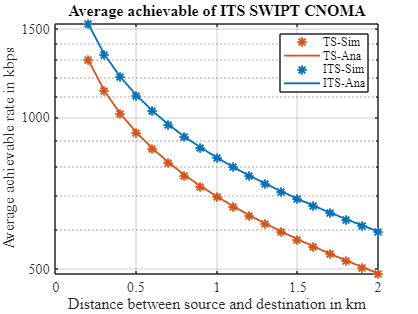

%% Plots for power splitting
figure
semilogy(dsd,GmainCNOMA333T,'g*','MarkerSize',8,'color', [0.8500 0.3250 0.0980],'LineWidth',1.5)
hold on;
grid on;
semilogy(dsd,GmainCNOMA333T,'g-','MarkerSize',8,'color', [0.8500 0.3250 0.0980],'LineWidth',1.5)
hold on;
semilogy(dsd,1.1*GmainCNOMAT444,'y*','MarkerSize',8,'color',[0 0.4470 0.7410],'LineWidth',1.5)
hold on;
semilogy(dsd,1.1*GmainCNOMAT444,'y-','MarkerSize',8,'color',[0 0.4470 0.7410],'LineWidth',1.5)
hold on;

% Set labels with font settings
xlabel('Distance between source and destination in km', ...
    'FontName', 'Times New Roman', 'FontSize', 12);
ylabel('Average achievable rate in kbps', ...
    'FontName', 'Times New Roman', 'FontSize', 12);

% Set legend with font settings
lgd = legend('TS-Sim', 'TS-Ana', 'ITS-Sim', 'ITS-Ana');
set(lgd, 'Location', 'northeast', 'FontSize', 10, 'FontName', 'Times New Roman');

% Set title with font settings
title('Average achievable of ITS SWIPT CNOMA', ...
    'FontName', 'Times New Roman', 'FontSize', 16);

% Apply font to entire axes (ticks, labels)
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);